# Demonstration of Twistor Theory for Maxwell Fields

This script demonstrates the TwistorMaxwellField class implementation Based on R.S. Ward's 1977 paper "On Self-Dual Gauge Fields"

clear; close all; clc;

## Example 1: Basic U(1) Maxwell Field (Electromagnetic Monopole)

fprintf('Example 1: U(1) Maxwell Field (Monopole-like Solution)\n');

Example 1: U(1) Maxwell Field (Monopole-like Solution)


fprintf('------------------------------------------------------\n\n');

------------------------------------------------------



Demonstrating Ward Construction for Self-Dual Gauge Fields

Step 1: Setting up twistor function g(W_α)...
Step 2: Computing gauge fields from twistor data...
Step 3: Checking self-duality condition...
Field is not self-dual (residual: 8.42e-01)
Step 4: Creating visualizations...



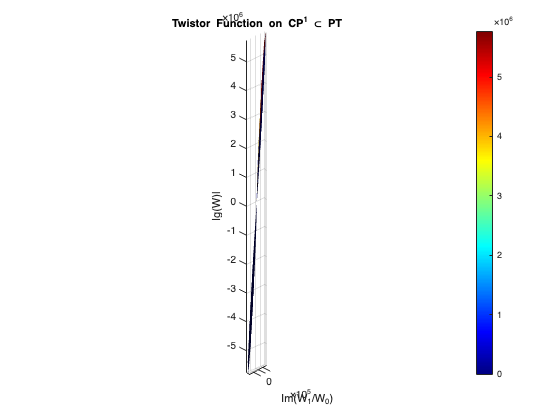

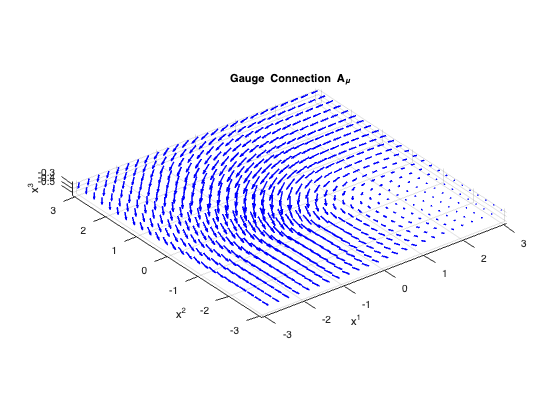

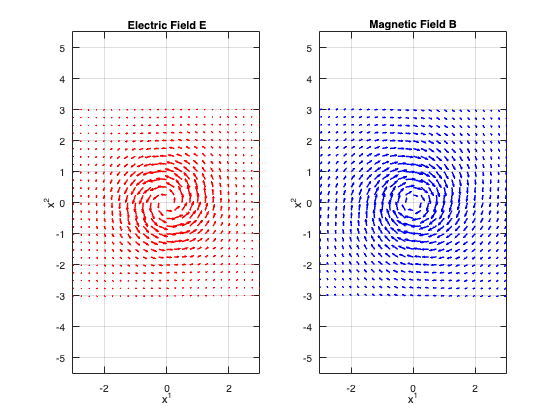

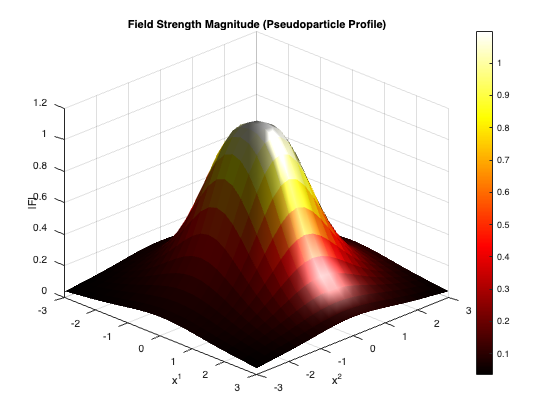


% Create a U(1) gauge field
maxwell_field = mlraut.TwistorMaxwellFieldScaled('gauge_group', 'U1', ...
                                    'n_points', 25, ...
                                    'x_range', [-3, 3]);

% Run the full Ward construction
maxwell_field.demonstrateWardConstruction();

## Example 2: Euclidean Signature (Instanton-like Solutions)

fprintf('\n\nExample 2: Euclidean Signature Field\n');



Example 2: Euclidean Signature Field


fprintf('------------------------------------\n\n');

------------------------------------



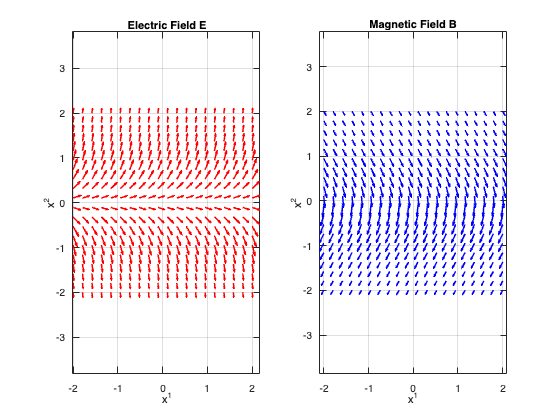


% Create field in Euclidean signature
euclidean_field = mlraut.TwistorMaxwellFieldScaled('gauge_group', 'U1', ...
                                      'slice_type', 'euclidean', ...
                                      'n_points', 20);

% Compute fields
euclidean_field.computeGaugeFields();

% Visualize
figure('Name', 'Euclidean Signature Fields');
euclidean_field.visualizeFieldStrength();

## Example 3: Custom Twistor Function

fprintf('\n\nExample 3: Custom Twistor Function\n');



Example 3: Custom Twistor Function


fprintf('----------------------------------\n\n');

----------------------------------



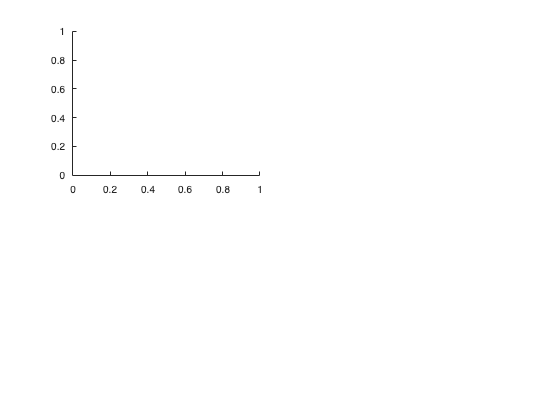


% Create field with custom parameters
custom_field = mlraut.TwistorMaxwellFieldScaled('n_points', 30);

% Define a custom twistor function (double monopole)
custom_field.twistor_function = @(W) exp(1i * W(1) / (W(2) + 0.5)) * ...
                                     exp(1i * W(1) / (W(2) - 0.5));

% Compute and visualize
custom_field.computeGaugeFields();

figure('Name', 'Custom Twistor Function - Double Monopole');
subplot(2, 2, 1);

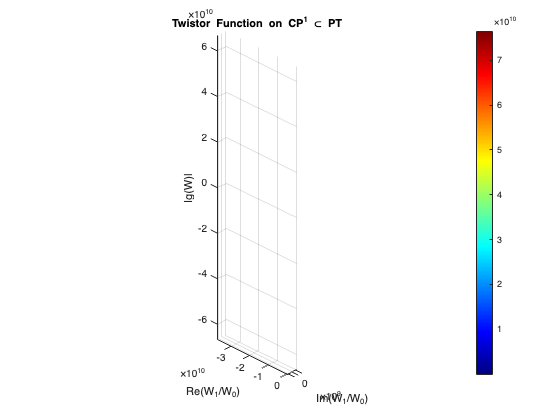

custom_field.visualizeTwistorFunction();

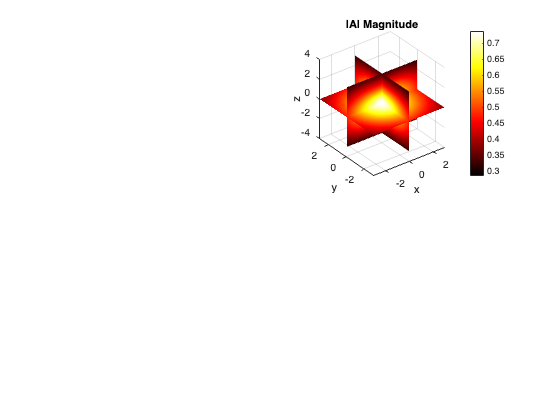


subplot(2, 2, 2);
% Visualize gauge potential magnitude
[X, Y, Z] = meshgrid(linspace(-3, 3, 30));
A_mag = sqrt(custom_field.gauge_potential.A1.^2 + ...
             custom_field.gauge_potential.A2.^2 + ...
             custom_field.gauge_potential.A3.^2);
slice(X, Y, Z, A_mag, 0, 0, 0);
shading interp;
colormap(hot);
colorbar;
title('|A| Magnitude');
xlabel('x'); ylabel('y'); zlabel('z');

## Example 4: Demonstrating the Spinor Formalism

fprintf('\n\nExample 4: 2-Spinor Notation\n');



Example 4: 2-Spinor Notation


fprintf('----------------------------\n\n');

----------------------------




% Show conversion between spacetime and spinor notation
test_point = [1, 0.5, -0.3, 0.8]; % (t, x, y, z)
x_spinor = custom_field.spacetimeToSpinor(test_point(1), test_point(2), ...
                                          test_point(3), test_point(4));

fprintf('Spacetime point: (t=%.2f, x=%.2f, y=%.2f, z=%.2f)\n', ...
        test_point(1), test_point(2), test_point(3), test_point(4));

Spacetime point: (t=1.00, x=0.50, y=-0.30, z=0.80)


fprintf('2-spinor representation:\n');

2-spinor representation:


disp(squeeze(x_spinor));

   1.0607 + 0.0000i  -0.2121 + 0.5657i
  -0.2121 - 0.5657i   0.3536 + 0.0000i




% Convert back
[t, x, y, z] = custom_field.spinorToSpacetime(x_spinor);
fprintf('\nConverted back: (t=%.2f, x=%.2f, y=%.2f, z=%.2f)\n', ...
        squeeze(t), squeeze(x), squeeze(y), squeeze(z));


Converted back: (t=1.00, x=0.50, y=-0.30, z=0.80)


## Example 5: Field Line Visualization

fprintf('\n\nExample 5: Field Line Visualization\n');



Example 5: Field Line Visualization


fprintf('-----------------------------------\n\n');

-----------------------------------



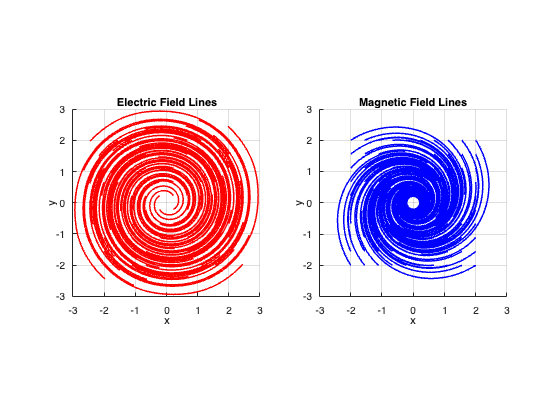


figure('Name', 'Electromagnetic Field Lines');

% Create starting points for field lines
[start_x, start_y] = meshgrid(linspace(-2, 2, 10), linspace(-2, 2, 10));
start_z = zeros(size(start_x));
start_points = [start_x(:), start_y(:), start_z(:)];

% Electric field lines
subplot(1, 2, 1);
hold on;

% Get field components at z=0 slice
mid_z = floor(maxwell_field.n_points / 2);
Ex = maxwell_field.field_strength.Ex(:, :, mid_z);
Ey = maxwell_field.field_strength.Ey(:, :, mid_z);

% Create interpolation functions
[X_grid, Y_grid] = meshgrid(linspace(-3, 3, maxwell_field.n_points));
Ex_interp = griddedInterpolant(X_grid', Y_grid', Ex', 'linear', 'none');
Ey_interp = griddedInterpolant(X_grid', Y_grid', Ey', 'linear', 'none');

% Trace field lines
for i = 1:size(start_points, 1)
    try
        % Simple field line tracing
        x_trace = start_points(i, 1);
        y_trace = start_points(i, 2);
        
        for step = 1:50
            Ex_val = Ex_interp(x_trace(end), y_trace(end));
            Ey_val = Ey_interp(x_trace(end), y_trace(end));
            
            if isnan(Ex_val) || isnan(Ey_val)
                break;
            end
            
            % Normalize and step
            norm_E = sqrt(Ex_val^2 + Ey_val^2) + 1e-10;
            dx = 0.1 * Ex_val / norm_E;
            dy = 0.1 * Ey_val / norm_E;
            
            x_trace(end+1) = x_trace(end) + dx;
            y_trace(end+1) = y_trace(end) + dy;
            
            % Check bounds
            if abs(x_trace(end)) > 3 || abs(y_trace(end)) > 3
                break;
            end
        end
        
        plot(x_trace, y_trace, 'r-', 'LineWidth', 1.5);
    catch
        % Skip problematic field lines
    end
end

axis equal;
xlim([-3, 3]); ylim([-3, 3]);
xlabel('x'); ylabel('y');
title('Electric Field Lines');
grid on;

% Magnetic field lines
subplot(1, 2, 2);
hold on;

Bx = maxwell_field.field_strength.Bx(:, :, mid_z);
By = maxwell_field.field_strength.By(:, :, mid_z);

% Create interpolation functions
Bx_interp = griddedInterpolant(X_grid', Y_grid', Bx', 'linear', 'none');
By_interp = griddedInterpolant(X_grid', Y_grid', By', 'linear', 'none');

% Trace magnetic field lines
for i = 1:size(start_points, 1)
    try
        x_trace = start_points(i, 1);
        y_trace = start_points(i, 2);
        
        for step = 1:50
            Bx_val = Bx_interp(x_trace(end), y_trace(end));
            By_val = By_interp(x_trace(end), y_trace(end));
            
            if isnan(Bx_val) || isnan(By_val)
                break;
            end
            
            norm_B = sqrt(Bx_val^2 + By_val^2) + 1e-10;
            dx = 0.1 * Bx_val / norm_B;
            dy = 0.1 * By_val / norm_B;
            
            x_trace(end+1) = x_trace(end) + dx;
            y_trace(end+1) = y_trace(end) + dy;
            
            if abs(x_trace(end)) > 3 || abs(y_trace(end)) > 3
                break;
            end
        end
        
        plot(x_trace, y_trace, 'b-', 'LineWidth', 1.5);
    catch
        % Skip problematic field lines
    end
end

axis equal;
xlim([-3, 3]); ylim([-3, 3]);
xlabel('x'); ylabel('y');
title('Magnetic Field Lines');
grid on;

## Summary

fprintf('\n\nSummary\n');



Summary


fprintf('-------\n');

-------


fprintf('This demonstration illustrated:\n');

This demonstration illustrated:


fprintf('1. Ward''s construction for self-dual gauge fields\n');

1. Ward's construction for self-dual gauge fields


fprintf('2. Conversion between spacetime and 2-spinor notation\n');

2. Conversion between spacetime and 2-spinor notation


fprintf('3. Visualization of gauge connections and field strengths\n');

3. Visualization of gauge connections and field strengths


fprintf('4. Pseudoparticle (instanton-like) solutions\n');

4. Pseudoparticle (instanton-like) solutions


fprintf('5. The relationship between twistor functions and gauge fields\n');

5. The relationship between twistor functions and gauge fields


fprintf('\nThe implementation provides a concrete realization of the\n');


The implementation provides a concrete realization of the


fprintf('abstract twistor theory for Maxwell fields, showing how\n');

abstract twistor theory for Maxwell fields, showing how


fprintf('complex vector bundles over twistor space encode gauge field\n');

complex vector bundles over twistor space encode gauge field


fprintf('information in spacetime.\n');

information in spacetime.
